clearvars; close all; clc;

# LF taps

The advised ratio is 10:1 (Sd LF: Sd ports)

The Sd of the 18Sound 12NTLW3500 is 531cm2.

Sdport	= 531*1e-4 / 10; % [m2]

% Dia in [mm] for 2 ports:
Dport	= sqrt(Sdport / 2 * 1e6 * 4/pi);

## Simulations

eglf			= 3;
egmf			= 2;
val				= mehresponsebuild(eglf,egmf);

### LF

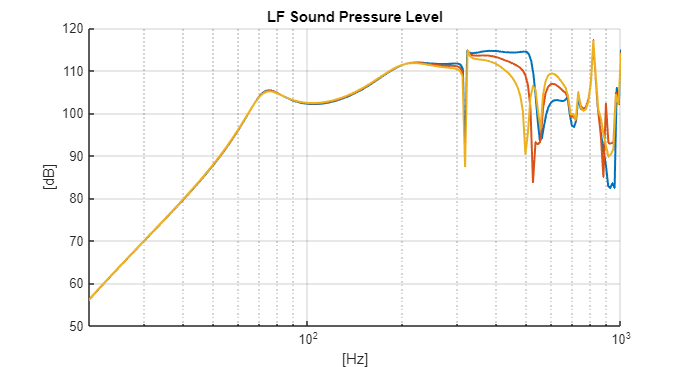

fig1				= figure;
fig1.Position		= [50 50 935 500];
fig1.Color			= "w";
ax1					= axes(fig1); hold on; grid on;
ax1.FontSize		= 10;
ax1.XScale			= "log";
ax1.XLim			= [val.lf.f(1) val.lf.f(end)];
ax1.XLabel.String	= "[Hz]";
ax1.YLabel.String	= "[dB]";
ax1.Title.String	= 'LF Sound Pressure Level';

% plot(ax1,val.lfbrm2.f,val.lfbrm2.spl,LineWidth=1,Color=[.5 .5 .5]);
% ax1.ColorOrderIndex = 1;
plot(ax1,val.lfctlf.f,val.lfctlf.spl,LineWidth=1.5)
plot(ax1,val.lfctlf2.f,val.lfctlf2.spl,LineWidth=1.5)
plot(ax1,val.lfctlf3.f,val.lfctlf3.spl,LineWidth=1.5)

### MF

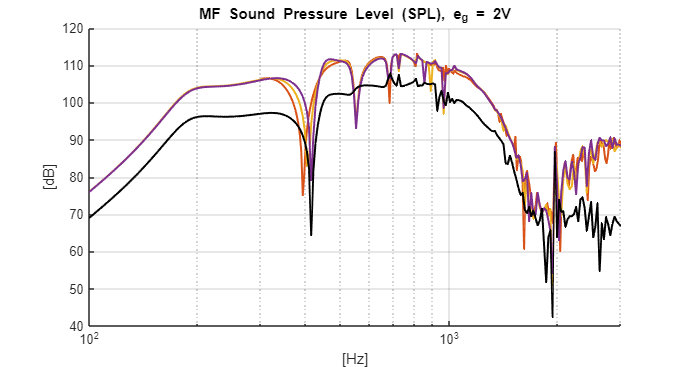

fig2				= figure;
fig2.Position		= [50 50 935 500];
fig2.Color			= "w";
ax2					= axes(fig2); hold on; grid on;
ax2.FontSize		= 10;
ax2.XScale			= "log";
ax2.XLim			= [1e2 val.mf.f(end)];
ax2.XLabel.String	= "[Hz]";
ax2.YLabel.String	= "[dB]";
ax2.Title.String	= ['MF Sound Pressure Level (SPL), e_g = ' num2str(egmf) 'V'];

% plot(ax2,val.mf.f,val.mf.spl,LineWidth=1,Color=[.5 .5 .5]);
ax2.ColorOrderIndex = 2;
plot(ax2,val.mfctlf.f,val.mfctlf.spl,LineWidth=1.5);
plot(ax2,val.mfctlf2.f,val.mfctlf2.spl,LineWidth=1.5);
plot(ax2,val.mfctlf3.f,val.mfctlf3.spl,LineWidth=1.5);
plot(ax2,val.mfctlf3ls.f,val.mfctlf3ls.spl,LineWidth=1.5,Color="k");

## LF + MF

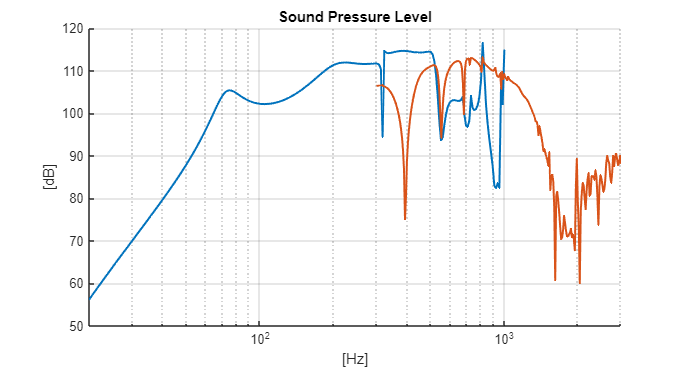

fig3				= figure;
fig3.Position		= [50 50 935 500];
fig3.Color			= "w";
ax3					= axes(fig3); hold on; grid on;
ax3.FontSize		= 10;
ax3.XScale			= "log";
ax3.XLim			= [val.lf.f(1) val.mf.f(end)];
ax3.XLabel.String	= "[Hz]";
ax3.YLabel.String	= "[dB]";
ax3.Title.String	= "Sound Pressure Level";

p1 = plot(ax3,val.lfctlf.f,val.lfctlf.spl,LineWidth=1.5);
% plot(ax3,val.lfctlf2.f,val.lfctlf2.spl,LineWidth=1.5);
% plot(ax3,val.lfctlf3.f,val.lfctlf3.spl,LineWidth=1.5);

ax3.ColorOrderIndex = 2;
plot(ax3,val.mfctlf.f,val.mfctlf.spl,LineWidth=1.5)

% % plot(ax3,val.mfctlf2.f,val.mfctlf2.spl,LineWidth=1.5);
% plot(ax3,val.mfctlf3.f,val.mfctlf3.spl,LineWidth=1.5);